Greenhouse Monitoring System

Instructions:


 - Script will run and record data continuously.


 - To PAUSE at any time, press Ctrl+C in Command Window.


 - Resume by typing dbcont in Command Window.


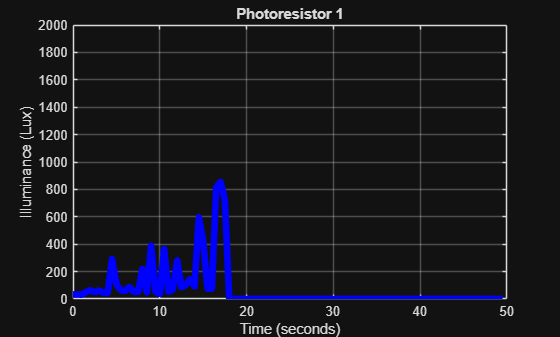

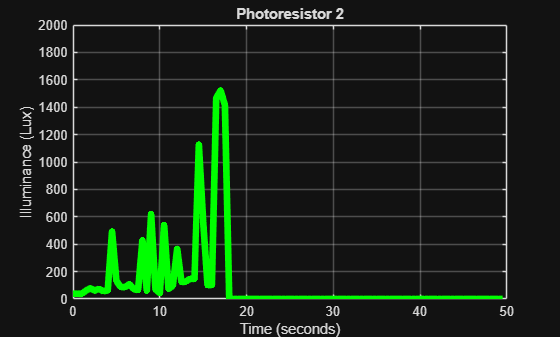

clear;
clc;

fprintf('Greenhouse Monitoring System');
fprintf('Instructions:\n');
fprintf(' - Script will run and record data continuously.\n');
fprintf(' - To PAUSE at any time, press Ctrl+C in Command Window.\n');
fprintf(' - Resume by typing dbcont in Command Window.\n');

MySerialPort= openSerial("COM3",115200); % Connect to serial port "COM3" and set Baud Speed

% initialize arrays for storing sensor data
data = [];
time = 0:0.5:49.5; % seconds
humidity = zeros(1,100); % percentage
% celsius = zeros(1,100); % degrees celsius
fahrenheit = zeros(1,100); % degrees fahrenheit
% heatIndexC = zeros(1,100); % degrees celsius
heatIndexF = zeros(1,100); % degrees fahrenheit
thermReading1 = zeros(1,100); % degrees celsius
photoReading1 = zeros(1,100); % lux
PIRReading = zeros(1,100); % volts
waterlevelReading = zeros(1,100); % inches
ledPower = zeros(1,100); % volts
fanPower = zeros(1,100); % volts

% Setup plots
figure('Name', 'Humidity');
humid = plot(time, humidity, 'Color', 'b', 'LineWidth', 2);
xlabel('Time (seconds)'); ylabel('Humidity (%)');
title('Greenhouse Humidity');
grid on; ylim([0 100]);

figure('Name', 'Greenhouse Temperature');
temp1 = plot(time, fahrenheit, 'Color', 'b', 'LineWidth', 2);
xlabel('Time (seconds)'); ylabel('Temperature (Fahrenheit)');
title('Greenhouse Temperature');
grid on; ylim([0 100]);

%figure('Name', 'Greenhouse Temperature');
%temp2 = plot(time, celsius, 'Color', 'b', 'LineWidth', 2);
%xlabel('Time (seconds)'); ylabel('Temperature (Celsius)');
%title('Greenhouse Temperature');
%grid on; ylim([0 100]);

figure('Name', 'Greenhouse Heat Index');
heatIndex1 = plot(time, heatIndexF, 'Color', 'b', 'LineWidth', 2);
xlabel('Time (seconds)'); ylabel('Heat Index (Fahrenheit)');
title('Greenhouse Heat Index');
grid on; ylim([0 100]);

%figure('Name', 'Greenhouse Heat Index');
%heatIndex2 = plot(time, heatIndexC, 'Color', 'b', 'LineWidth', 2);
%xlabel('Time (seconds)'); ylabel('Heat Index (Celsius)');
%title('Greenhouse Heat Index');
%grid on; ylim([0 100]);

figure('Name', 'Thermistor 1');
therm1 = plot(time, thermReading1, 'Color', 'b', 'LineWidth', 2);
xlabel('Time (seconds)'); ylabel('Temperature (Fahrenheit)');
title('Thermistor 1');
grid on; ylim([0 100]);

figure('Name', 'Photoresistor 1');
photo1 = plot(time, photoReading1, 'Color', 'b', 'LineWidth', 5);
xlabel('Time (seconds)'); ylabel('Illuminance (Lux)');
title('Photoresistor 1');
grid on; ylim([0 2000]);

figure('Name', 'Motion Sensor Reading');
motionSensed = plot(time, PIRReading, 'Color', 'b', 'LineWidth', 5);
xlabel('Time (seconds)'); ylabel('Voltage (Volts)');
title('Motion Sensor');
grid on; ylim([0 2]);

figure('Name', 'Water Level Reading');
waterLevel = plot(time, waterlevelReading, 'Color', 'b', 'LineWidth', 5);
xlabel('Time (seconds)'); ylabel('Height (Inches)');
title('Water Level Sensor');
grid on; ylim([0 2]);

figure('Name', 'LED Power');
led = plot(time, ledPower, 'Color', 'b', 'LineWidth', 2);
xlabel('Time (seconds)'); ylabel('Power (Volts)');
title('LED Brightness');
grid on; ylim([0 6]);

figure('Name', 'Fan Power');
fan = plot(time, fanPower, 'Color', 'b', 'LineWidth', 2);
xlabel('Time (seconds)'); ylabel('Power (Volts)');
title('Fan Power');
grid on; ylim([0 6]);

run = true; % program will loop indefinitely until stopped
i = 1; % array index
while run == true
    % this collects data builds a vector array where every revived number is separated by a " , " 
    % the packet is finished and returned when a newline character is
    % recived. on an arduino this is made by Serial.println()
    receivedData = readSerialPacket(MySerialPort);
    data = [data; receivedData];

    % Update the plots with new data
    % Shift data along
    humidity = [receivedData(1), humidity(1:end-1)];
    fahrenheit = [receivedData(3), fahrenheit(1:end-1)];
    heatIndexF = [receivedData(5), heatIndexF(1:end-1)];
    thermReading1 = [receivedData(6), thermReading1(1:end-1)];
    photoReading1 = [receivedData(7), photoReading1(1:end-1)];
    PIRReading = [receivedData(9), PIRReading(1:end-1)];
    waterlevelReading = [receivedData(10), waterlevelReading(1:end-1)];
    ledPower = [receivedData(11), ledPower(1:end-1)];
    fanPower = [receivedData(12), fanPower(1:end-1)];
    
    % Update the corresponding plots
    set(humid, 'YData', humidity);
    set(temp1, 'YData', fahrenheit);
    set(heatIndex1, 'YData', heatIndexF);
    set(therm1, 'YData', thermReading1);
    set(photo1, 'YData', photoReading1);
    set(motionSensed, 'YData', PIRReading);
    set(waterLevel, 'YData', waterlevelReading);
    set(led, 'YData', ledPower);
    set(fan, 'YData', fanPower);

    drawnow limitrate;

    i  = i + 1; % increment array index
end

clear MySerialPort ; % This is a MUST HAVE it releases the serial port from memory !!!!